# Convolution Testing

% Reset the project to default state
clear;clc;close

% Add the dependencies to the project path relative to the project folder
addpath('Functions')
addpath('AudioSamples')

% Delay Line Parameters
decay = 1.106;
feedback = 0.57;
amplitude = 0.47;

% Low Pass Filter Parameters
LPFfrequency = 3009;
q = 0.708;

## Signals

% Signal 1
[x,fs] = audioread('AudioSamples/Guitar.wav');   % Read in signal
[xMid, xSide] = midSideEncode(x);
% Signal 2
xRIR = audioread('AudioSamples/SilverVerb_IR.wav');
[xRIRMid, xRIRSide] = midSideEncode(xRIR);
% Signal 3
xDelay = LPFDelay(xMid, decay, feedback, amplitude, LPFfrequency, q, fs);
% Signal 4

[snareMid, snareSide] = midSideEncode(audioread('AudioSamples/Snare.wav'));

## Processing

% Output signal
% y = LPFDelay(xMid, decay, feedback, amplitude, LPFfrequency, q, fs);
% y = .001*conv(xMid,xDelay,'full');

y = 0.01*conv(xMid, snareMid, 'same');


## Analysis

audioAnalysisX = xMid(1:length(xMid)/2);
audioAnalysisY = y(1:length(y)/2);

signalsLgd = ["Input Signal" "Output Signal"]

signalsLgd = 1×2 string array
    "Input Signal"    "Output Signal"


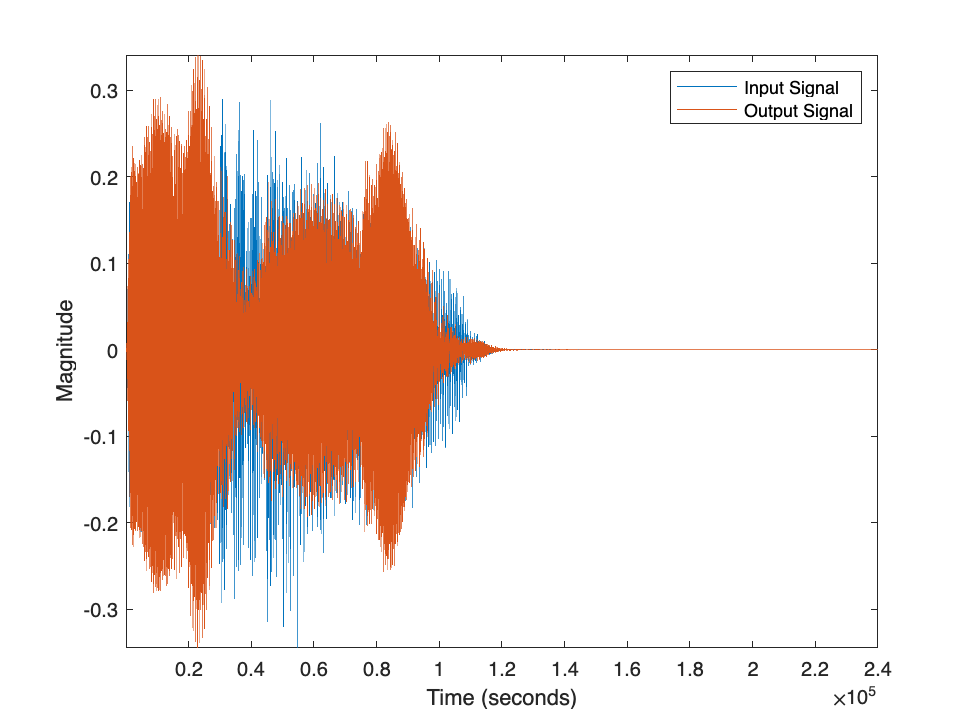


plot(audioAnalysisX)
hold on
plot(audioAnalysisY)
hold off
axis tight
xlabel("Time (seconds)")
ylabel("Magnitude")
legend(signalsLgd)


% Play back the first half of the audio file
% sound(audioAnalysis, fs)